%% QUADRATIC TIME SERIES MODELING APPROACH FOR FRANCE CO2 EMISSIONS
% This script implements quadratic detrending followed by ARIMA modeling with grid search

%% SECTION 1 — Load and Prepare Data
FranceData = readtable("FranceDatawithPop.csv");

% Convert 'Year' to datetime
FranceData.Year = datetime(FranceData.Year, 1, 1);

% Convert to timetable
FranceTT = table2timetable(FranceData, "RowTimes", "Year");

% Split into training and test sets
selectedCut = datetime(2018, 1, 1);
trainData = FranceTT(FranceTT.Year < selectedCut, :);
testData  = FranceTT(FranceTT.Year >= selectedCut, :);

fprintf("✅ Height of training data: %d\n", height(trainData));

✅ Height of training data: 208


fprintf("✅ Height of test data: %d\n", height(testData));

✅ Height of test data: 6



%% SECTION 2 — Check Initial Stationarity
y = trainData.Total;
[h_original, p_original] = adftest(y);

fprintf('\n===== STATIONARITY CHECK (Original Data) =====\n');


===== STATIONARITY CHECK (Original Data) =====


if h_original == 0
    fprintf('⚠️  Original series is NOT stationary (p=%.4f)\n', p_original);
else
    fprintf('✅ Original series is stationary (p=%.4f)\n', p_original);
end

⚠️  Original series is NOT stationary (p=0.8572)



% Log transform to stabilize variance
yLog = log(trainData.Total + 1);
[h_log, p_log] = adftest(yLog);
fprintf('Log-transformed: h=%d, p=%.4f\n', h_log, p_log);

Log-transformed: h=0, p=0.9962



%% SECTION 3 — Quadratic Detrending
fprintf('\n===== QUADRATIC DETRENDING =====\n');


===== QUADRATIC DETRENDING =====



% Create time variable (numeric years for polynomial fitting)
t = year(trainData.Year);
t_normalized = (t - min(t)) / (max(t) - min(t));  % Normalize to [0,1] for stability

% Fit quadratic polynomial to log-transformed data
quadraticModel = polyfit(t_normalized, yLog, 2);
trendQuadratic = polyval(quadraticModel, t_normalized);

% Compute detrended residuals
yDetrended = yLog - trendQuadratic;

fprintf('✅ Quadratic polynomial coefficients: [%.6f, %.6f, %.6f]\n', quadraticModel);

✅ Quadratic polynomial coefficients: [-6.269012, 11.004903, 1.112583]



%% SECTION 4 — Check Stationarity After Detrending
[h_detrend, p_detrend] = adftest(yDetrended);

fprintf('\n===== STATIONARITY CHECK (After Quadratic Detrending) =====\n');


===== STATIONARITY CHECK (After Quadratic Detrending) =====


if h_detrend == 1
    fprintf('✅ Detrended series is STATIONARY (p=%.4f)\n', p_detrend);
else
    fprintf('⚠️  Detrended series is still NOT stationary (p=%.4f)\n', p_detrend);
    fprintf('   Consider differencing if needed.\n');
end

✅ Detrended series is STATIONARY (p=0.0092)


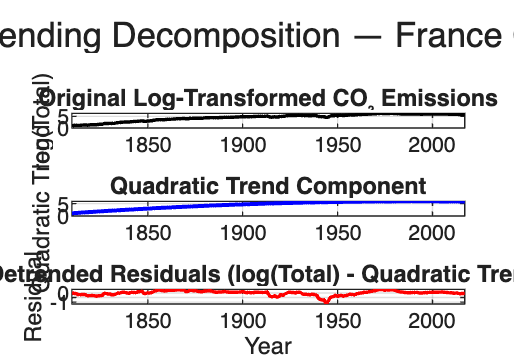


%% SECTION 5 — Visualize Decomposition
figure('Position', [100 100 1000 700]);

subplot(3,1,1);
plot(trainData.Year, yLog, 'k-', 'LineWidth', 1.3);
title('Original Log-Transformed CO₂ Emissions');
ylabel('log(Total)'); grid on;

subplot(3,1,2);
plot(trainData.Year, trendQuadratic, 'b-', 'LineWidth', 1.5);
title('Quadratic Trend Component');
ylabel('Quadratic Trend'); grid on;

subplot(3,1,3);
plot(trainData.Year, yDetrended, 'r-', 'LineWidth', 1.3);
title('Detrended Residuals (log(Total) - Quadratic Trend)');
xlabel('Year'); ylabel('Residual'); grid on;

sgtitle('Quadratic Detrending Decomposition — France CO₂ Emissions');


%% SECTION 6 — ACF and PACF Analysis
fprintf('\n===== ACF/PACF ANALYSIS =====\n');


===== ACF/PACF ANALYSIS =====


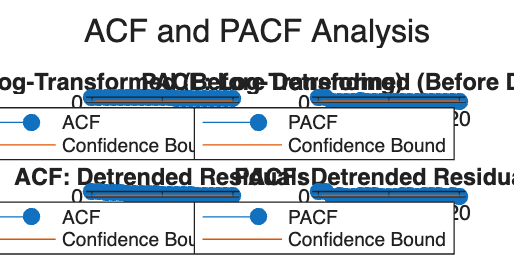


figure('Position', [100 100 1000 500]);

subplot(2,2,1);
autocorr(yLog);
title('ACF: Log-Transformed (Before Detrending)');

subplot(2,2,2);
parcorr(yLog);
title('PACF: Log-Transformed (Before Detrending)');

subplot(2,2,3);
autocorr(yDetrended);
title('ACF: Detrended Residuals');

subplot(2,2,4);
parcorr(yDetrended);
title('PACF: Detrended Residuals');

sgtitle('ACF and PACF Analysis');


fprintf('✅ Review ACF/PACF plots to identify ARIMA parameters\n');

✅ Review ACF/PACF plots to identify ARIMA parameters



%% SECTION 7 — Grid Search for Best ARIMA Parameters
fprintf('\n===== GRID SEARCH FOR ARIMA PARAMETERS =====\n');


===== GRID SEARCH FOR ARIMA PARAMETERS =====



% Define parameter ranges
p_range = 0:5;  % AR order
q_range = 0:5;  % MA order
d = 0;          % No differencing needed after detrending

% Initialize results storage
numModels = length(p_range) * length(q_range);
results = struct('p', {}, 'q', {}, 'AIC', {}, 'BIC', {}, 'RMSE_train', {}, 'RMSE_test', {});
idx = 1;

% Prepare test data
t_test = year(testData.Year);
t_test_normalized = (t_test - min(t)) / (max(t) - min(t));
trendTest = polyval(quadraticModel, t_test_normalized);
yTestLog = log(testData.Total + 1);
horizon = height(testData);

fprintf('Testing %d ARIMA models...\n', numModels);

Testing 36 ARIMA models...



for p = p_range
    for q = q_range
        try
            % Skip ARIMA(0,0,0)
            if p == 0 && q == 0
                continue;
            end
            
            % Fit ARIMA model on detrended data
            mdl = arima(p, d, q);
            [estMdl, ~, logL] = estimate(mdl, yDetrended, 'Display', 'off');
            
            % Calculate training RMSE
            res = infer(estMdl, yDetrended);
            rmse_train = sqrt(mean(res.^2));
            
            % Forecast on test period (detrended)
            [yhat_detrended, ~] = forecast(estMdl, horizon, 'Y0', yDetrended);
            
            % Add back quadratic trend for test period
            yhat_log = yhat_detrended + trendTest;
            yhat = exp(yhat_log) - 1;
            
            % Calculate test RMSE
            rmse_test = sqrt(mean((yhat - testData.Total).^2));
            
            % Calculate AIC and BIC
            n = length(yDetrended);
            numParams = p + q + 1;  % AR + MA + constant
            aic = -2*logL + 2*numParams;
            bic = -2*logL + numParams*log(n);
            
            % Store results
            results(idx).p = p;
            results(idx).q = q;
            results(idx).AIC = aic;
            results(idx).BIC = bic;
            results(idx).RMSE_train = rmse_train;
            results(idx).RMSE_test = rmse_test;
            results(idx).model = estMdl;
            
            idx = idx + 1;
            
        catch ME
            fprintf('⚠️  ARIMA(%d,0,%d) failed: %s\n', p, q, ME.message);
        end
    end
end

fprintf('✅ Successfully tested %d models\n', length(results));

✅ Successfully tested 35 models



%% SECTION 8 — Display Top Models
fprintf('\n===== TOP 5 MODELS BY TEST RMSE =====\n');


===== TOP 5 MODELS BY TEST RMSE =====



% Sort results by test RMSE (keep as struct array)
[~, sortIdx] = sort([results.RMSE_test]);
results = results(sortIdx);

% Display top 5
fprintf('%-15s %-8s %-10s %-12s %-12s\n', 'Model', 'AIC', 'BIC', 'Train RMSE', 'Test RMSE');

Model           AIC      BIC        Train RMSE   Test RMSE   


fprintf('%s\n', repmat('-', 1, 70));

----------------------------------------------------------------------



for i = 1:min(5, length(results))
    fprintf('ARIMA(%d,0,%d)   %8.2f  %10.2f  %12.4f  %12.4f\n', ...
        results(i).p, results(i).q, ...
        results(i).AIC, results(i).BIC, ...
        results(i).RMSE_train, results(i).RMSE_test);
end

ARIMA(5,0,5)    -420.72     -384.01        0.0835       34.3493
ARIMA(1,0,0)    -425.96     -419.28        0.0861       35.2344
ARIMA(3,0,0)    -424.90     -411.55        0.0855       35.3347
ARIMA(4,0,3)    -421.43     -394.73        0.0845       35.4018
ARIMA(1,0,2)    -425.19     -411.84        0.0854       35.7510



% Identify best model
bestIdx = 1;
bestModel = results(bestIdx).model;
fprintf('\n✅ BEST MODEL: ARIMA(%d,0,%d)\n', results(bestIdx).p, results(bestIdx).q);


✅ BEST MODEL: ARIMA(5,0,5)


fprintf('   Test RMSE: %.4f\n', results(bestIdx).RMSE_test);

   Test RMSE: 34.3493


fprintf('   AIC: %.2f | BIC: %.2f\n', results(bestIdx).AIC, results(bestIdx).BIC);

   AIC: -420.72 | BIC: -384.01



%% SECTION 9 — Generate Predictions for Training Data
fprintf('\n===== GENERATING PREDICTIONS FOR TRAINING DATA =====\n');


===== GENERATING PREDICTIONS FOR TRAINING DATA =====



% For training data, use fitted values (in-sample predictions)
residuals_train = infer(bestModel, yDetrended);
yDetrended_fitted = yDetrended - residuals_train;

% Add back trend and convert to original scale
yLog_fitted_train = yDetrended_fitted + trendQuadratic;
yPredicted_train = exp(yLog_fitted_train) - 1;

% Calculate training RMSE
trainRMSE = sqrt(mean((yPredicted_train - trainData.Total).^2));
fprintf('Training RMSE: %.4f\n', trainRMSE);

Training RMSE: 14.0966



%% SECTION 10 — Generate Predictions for Test Data
fprintf('\n===== GENERATING PREDICTIONS FOR TEST DATA =====\n');


===== GENERATING PREDICTIONS FOR TEST DATA =====



% Forecast on test period (detrended)
[yhat_detrended_test, ~] = forecast(bestModel, horizon, 'Y0', yDetrended);

% Add back quadratic trend for test period
yhat_log_test = yhat_detrended_test + trendTest;
yPredicted_test = exp(yhat_log_test) - 1;

% Calculate test RMSE
testRMSE = sqrt(mean((yPredicted_test - testData.Total).^2));
fprintf('Test RMSE: %.4f\n', testRMSE);

Test RMSE: 34.3493


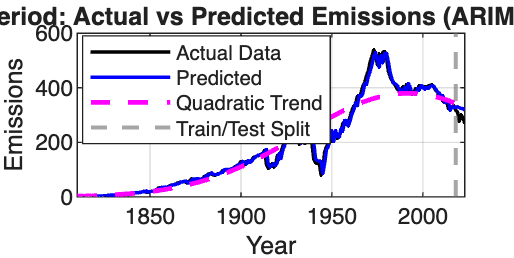


%% SECTION 11 — Combined Visualization
figure('Position', [100 100 1200 600]);

% Combine training and test data
combinedActualTime = [trainData.Year; testData.Year];
combinedActualTotal = [trainData.Total; testData.Total];
combinedPredictedTime = [trainData.Year; testData.Year];
combinedPredictedTotal = [yPredicted_train; yPredicted_test];

% Combine quadratic trend (convert from log scale to original scale)
trendQuadratic_original = exp(trendQuadratic) - 1;
trendTest_original = exp(trendTest) - 1;
combinedTrendTime = [trainData.Year; testData.Year];
combinedTrend = [trendQuadratic_original; trendTest_original];

% Plot actual data as ONE connected line
plot(combinedActualTime, combinedActualTotal, 'k-', 'LineWidth', 1.3, 'DisplayName', 'Actual Data');
hold on;
% Plot predicted data as ONE connected line
plot(combinedPredictedTime, combinedPredictedTotal, 'b-', 'LineWidth', 1.3, 'DisplayName', 'Predicted');
% Plot quadratic trend
plot(combinedTrendTime, combinedTrend, 'm--', 'LineWidth', 1.8, 'DisplayName', 'Quadratic Trend');
% Add vertical line to mark train/test split
xline(selectedCut, '--', 'Color', [0.5 0.5 0.5], 'LineWidth', 1.5, 'DisplayName', 'Train/Test Split');
xlabel('Year'); ylabel('Emissions');
title(sprintf('Full Period: Actual vs Predicted Emissions (ARIMA(%d,0,%d))', results(bestIdx).p, results(bestIdx).q));
legend('Location', 'best'); grid on;
hold off;


%% SECTION 12 — Residual Diagnostics for Best Model
fprintf('\n===== RESIDUAL DIAGNOSTICS =====\n');


===== RESIDUAL DIAGNOSTICS =====


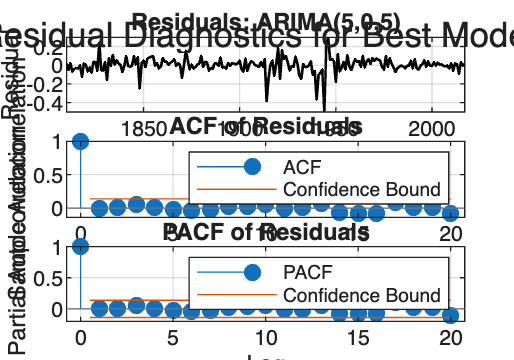


resBest = infer(bestModel, yDetrended);

figure('Position', [100 100 1000 700]);

subplot(3,1,1);
plot(trainData.Year(end-length(resBest)+1:end), resBest, 'k-', 'LineWidth', 1);
title(sprintf('Residuals: ARIMA(%d,0,%d)', results(bestIdx).p, results(bestIdx).q));
ylabel('Residual'); grid on;

subplot(3,1,2);
autocorr(resBest);
title('ACF of Residuals');

subplot(3,1,3);
parcorr(resBest);
title('PACF of Residuals');

sgtitle('Residual Diagnostics for Best Model');

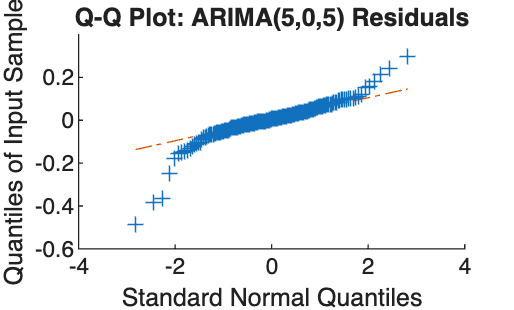


% Q-Q plot
figure;
qqplot(resBest);
titleText = sprintf('Q-Q Plot: ARIMA(%d,0,%d) Residuals', results(bestIdx).p, results(bestIdx).q);
title(titleText);


fprintf('\n✅ Analysis complete! Review diagnostics to ensure model adequacy.\n');


✅ Analysis complete! Review diagnostics to ensure model adequacy.



%% SECTION 13 — Summary
fprintf('\n===== FINAL SUMMARY =====\n');


===== FINAL SUMMARY =====


fprintf('Best Model: ARIMA(%d,0,%d)\n', results(bestIdx).p, results(bestIdx).q);

Best Model: ARIMA(5,0,5)


fprintf('Training RMSE: %.4f\n', trainRMSE);

Training RMSE: 14.0966


fprintf('Test RMSE:     %.4f\n', testRMSE);

Test RMSE:     34.3493


fprintf('AIC: %.2f | BIC: %.2f\n', results(bestIdx).AIC, results(bestIdx).BIC);

AIC: -420.72 | BIC: -384.01



%% Save results
save('QuadraticModel_Results.mat', 'quadraticModel', 'bestModel', 'results', ...
     'trainData', 'testData', 'yDetrended', 't_normalized', ...
     'yPredicted_train', 'yPredicted_test');
fprintf('✅ Results saved to QuadraticModel_Results.mat\n');

✅ Results saved to QuadraticModel_Results.mat
